# Deploy Your PHM Solutions to Desktop Embedded & Cloud Systems

Load Dataset

clear; clc; close all;
addpath('dependencies');
load('shuffledFleetData.mat', 'shuffledData', 'mwIDs');

## Prepare numeric array — strip FailureMode, RUL, uniqueID

Keep 362 columns: 360 numeric features + FlightClass + cycle

featureCols = setdiff(shuffledData.Properties.VariableNames, ...
    {'FailureMode','RUL','uniqueID'}, 'stable');
numericData = table2array(shuffledData(:, featureCols)); % 9900x362 double
engineIDs = shuffledData.uniqueID;                        % 9900x1 string

fprintf("Numeric array: %dx%d double\n", size(numericData,1), size(numericData,2));

Numeric array: 9900x362 double


fprintf("Removed columns: FailureMode (361), RUL (363), uniqueID (365)\n");

Removed columns: FailureMode (361), RUL (363), uniqueID (365)


fprintf("Kept columns: 360 features + FlightClass (362) + cycle (364)\n");

Kept columns: 360 features + FlightClass (362) + cycle (364)


## Batch Classification — Verify predict works on raw array

ashaMdl = load('dependencies/classificationMdl.mat','ashaMdl').ashaMdl;
[predFaultClass, predConfScores] = predict(ashaMdl, numericData);
fprintf("\nBatch classification: %d rows, %d classes — OK\n", ...
    length(predFaultClass), size(predConfScores, 2));


Batch classification: 9900 rows, 8 classes — OK


## Simulate Microservice — 9 Engines Per Tick

Real deployment: JSON payload → Nx362 double + N engine IDs Dashboard updates 9 engines at a time (staggered visual refresh)

nTotal = height(shuffledData);
batchSize = 9;
nTicks = ceil(nTotal / batchSize);
fprintf("\nFleet: %d observations, batch size: %d, ticks: %d\n", ...
    nTotal, batchSize, nTicks);


Fleet: 9900 observations, batch size: 9, ticks: 1100



fprintf("\n--- Simulating microservice calls (9 engines/tick) ---\n");


--- Simulating microservice calls (9 engines/tick) ---


sampleTicks = [1, 50, 100, 200, 500, 800, 1000, nTicks];

for tick = 1:nTicks
    startIdx = (tick - 1) * batchSize + 1;
    endIdx = min(tick * batchSize, nTotal);

    tickArray = numericData(startIdx:endIdx, :);   % up to 9x362 double
    tickIDs = engineIDs(startIdx:endIdx);           % up to 9x1 string

    [faultClass, confScores, rulEst, hiValues] = monitorEngineFleet(tickArray, tickIDs);

    if ismember(tick, sampleTicks)
        nBatch = endIdx - startIdx + 1;
        fprintf("\n  Tick %4d (rows %d-%d, %d engines):\n", ...
            tick, startIdx, endIdx, nBatch);

        faulted = faultClass ~= "Healthy" & faultClass ~= "All";
        nFaulted = sum(faulted);
        fprintf("    Faulted: %d / %d\n", nFaulted, nBatch);

        % Show all engines in this tick
        for j = 1:nBatch
            if isinf(rulEst(j))
                rulStr = 'Inf';
            else
                rulStr = sprintf('%d', rulEst(j));
            end
            trueRUL = shuffledData.RUL(startIdx + j - 1);
            fprintf("      %s | Pred: %-10s | HI: %+.3f | RUL: %4s (true: %d)\n", ...
                tickIDs(j), string(faultClass(j)), hiValues(j), rulStr, trueRUL);
        end
    end
end


  Tick    1 (rows 1-9, 9 engines):


    Faulted: 2 / 9


      MW-371 | Pred: HPC        | HI: +0.501 | RUL:   51 (true: 49)
      MW-162 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 70)
      MW-731 | Pred: All        | HI: +0.223 | RUL:   23 (true: 25)
      MW-130 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 88)
      MW-437 | Pred: All        | HI: +0.421 | RUL:   42 (true: 42)
      MW-157 | Pred: HPT + LPT  | HI: +0.380 | RUL:   35 (true: 33)
      MW-741 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 56)
      MW-366 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 86)
      MW-628 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 94)



  Tick   50 (rows 442-450, 9 engines):


    Faulted: 4 / 9


      MW-365 | Pred: HPT + LPT  | HI: +0.074 | RUL:    4 (true: 7)
      MW-141 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 58)
      MW-606 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 76)
      MW-563 | Pred: HPC + LPC  | HI: +0.549 | RUL:   58 (true: 48)
      MW-443 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 51)
      MW-161 | Pred: HPT + LPT  | HI: +0.136 | RUL:   11 (true: 10)
      MW-130 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 84)
      MW-731 | Pred: HPT + LPT  | HI: +0.336 | RUL:   31 (true: 21)
      MW-205 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 75)



  Tick  100 (rows 892-900, 9 engines):


    Faulted: 5 / 9


      MW-774 | Pred: Fan        | HI: +0.632 | RUL:   65 (true: 41)
      MW-152 | Pred: HPT + LPT  | HI: +0.199 | RUL:   27 (true: 19)
      MW-735 | Pred: HPT        | HI: +0.680 | RUL:   61 (true: 57)
      MW-757 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 57)
      MW-223 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 68)
      MW-258 | Pred: LPT        | HI: +0.562 | RUL:   56 (true: 44)
      MW-618 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 65)
      MW-130 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 79)
      MW-196 | Pred: Fan        | HI: +0.262 | RUL:   26 (true: 44)



  Tick  200 (rows 1792-1800, 9 engines):


    Faulted: 4 / 9


      MW-616 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 53)
      MW-873 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 51)
      MW-922 | Pred: HPT + LPT  | HI: +0.308 | RUL:   32 (true: 37)
      MW-520 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 53)
      MW-498 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 81)
      MW-371 | Pred: HPC        | HI: +0.355 | RUL:   37 (true: 31)
      MW-399 | Pred: HPC + LPC  | HI: +0.021 | RUL:   15 (true: 0)
      MW-161 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 59)
      MW-223 | Pred: HPC + LPC  | HI: +0.554 | RUL:   58 (true: 59)



  Tick  500 (rows 4492-4500, 9 engines):


    Faulted: 6 / 9


      MW-701 | Pred: LPT        | HI: +0.370 | RUL:   38 (true: 50)
      MW-240 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 59)
      MW-258 | Pred: LPT        | HI: +0.093 | RUL:   16 (true: 8)
      MW-610 | Pred: LPT        | HI: +0.434 | RUL:   41 (true: 39)
      MW-161 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 58)
      MW-162 | Pred: HPT + LPT  | HI: +0.300 | RUL:   26 (true: 25)
      MW-636 | Pred: HPT        | HI: +0.108 | RUL:   15 (true: 8)
      MW-922 | Pred: HPT + LPT  | HI: +0.060 | RUL:    4 (true: 10)
      MW-606 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 56)



  Tick  800 (rows 7192-7200, 9 engines):


    Faulted: 1 / 9


      MW-980 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 81)
      MW-995 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 70)
      MW-774 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 72)
      MW-141 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 53)
      MW-566 | Pred: HPC + LPC  | HI: +0.230 | RUL:   23 (true: 26)
      MW-616 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 71)
      MW-563 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 80)
      MW-363 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 57)
      MW-858 | Pred: All        | HI: +0.483 | RUL:   49 (true: 34)



  Tick 1000 (rows 8992-9000, 9 engines):


    Faulted: 0 / 9


      MW-993 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 65)
      MW-666 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 55)
      MW-437 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 52)
      MW-162 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 68)
      MW-139 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 73)
      MW-265 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 51)
      MW-395 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 60)
      MW-858 | Pred: All        | HI: +0.189 | RUL:   33 (true: 16)
      MW-995 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 52)



  Tick 1100 (rows 9892-9900, 9 engines):


    Faulted: 1 / 9


      MW-369 | Pred: Fan        | HI: +0.419 | RUL:   33 (true: 43)
      MW-694 | Pred: All        | HI: +0.576 | RUL:   48 (true: 46)
      MW-741 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 57)
      MW-839 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 60)
      MW-628 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 90)
      MW-936 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 64)
      MW-162 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 59)
      MW-265 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 51)
      MW-322 | Pred: Healthy    | HI: +1.000 | RUL:  Inf (true: 40)


%% Final Fleet Summary — Process last full cycle of all 99 engines
fprintf("\n\n=== FINAL VERIFICATION — Last cycle per engine ===\n");



=== FINAL VERIFICATION — Last cycle per engine ===



% Get last observation per engine
lastRows = zeros(numel(mwIDs), 1);
for e = 1:numel(mwIDs)
    idx = find(engineIDs == mwIDs(e), 1, 'last');
    lastRows(e) = idx;
end

finalArray = numericData(lastRows, :);
finalIDs = engineIDs(lastRows);
[faultClass, ~, rulEst, hiValues] = monitorEngineFleet(finalArray, finalIDs);

% Fault distribution
cats = unique(faultClass);
fprintf("\nFault Distribution:\n");


Fault Distribution:


for c = 1:numel(cats)
    n = sum(faultClass == cats(c));
    if n > 0
        fprintf("  %-12s: %3d engines (%5.1f%%)\n", cats(c), n, n/numel(mwIDs)*100);
    end
end

  All         :   8 engines (  8.1%)
  Fan         :   6 engines (  6.1%)
  HPC         :   4 engines (  4.0%)
  HPC + LPC   :   4 engines (  4.0%)
  HPT         :   7 engines (  7.1%)
  HPT + LPT   :   9 engines (  9.1%)
  Healthy     :  57 engines ( 57.6%)
  LPT         :   4 engines (  4.0%)



% RUL summary
faulted = faultClass ~= "Healthy" & faultClass ~= "All";
finiteRUL = rulEst(faulted & ~isinf(rulEst));
fprintf("\nRUL Estimates (faulted, finite):\n");


RUL Estimates (faulted, finite):


fprintf("  Count: %d / %d faulted\n", numel(finiteRUL), sum(faulted));

  Count: 34 / 34 faulted


if ~isempty(finiteRUL)
    fprintf("  Min: %d | Max: %d | Mean: %.1f cycles\n", ...
        min(finiteRUL), max(finiteRUL), mean(finiteRUL));
end

  Min: 0 | Max: 70 | Mean: 32.7 cycles



% Critical engines
critical = faulted & rulEst < 10 & ~isinf(rulEst);
fprintf("\nCRITICAL (RUL < 10): %d engines\n", sum(critical));


CRITICAL (RUL < 10): 8 engines


critIdx = find(critical);
for j = critIdx(1:min(10, end))'
    fprintf("  %s | %s | HI: %+.3f | RUL: %d\n", ...
        finalIDs(j), string(faultClass(j)), hiValues(j), rulEst(j));
end

  MW-119 | HPT | HI: +0.096 | RUL: 9
  MW-185 | Fan | HI: +0.045 | RUL: 4
  MW-240 | HPC + LPC | HI: +0.066 | RUL: 6
  MW-354 | HPT + LPT | HI: +0.000 | RUL: 0
  MW-357 | HPT + LPT | HI: +0.000 | RUL: 0
  MW-421 | LPT | HI: +0.107 | RUL: 9
  MW-606 | LPT | HI: +0.000 | RUL: 0
  MW-721 | LPT | HI: +0.000 | RUL: 0



fprintf("\n=== Microservice interface verified (Nx362 double + engineIDs) ===\n");


=== Microservice interface verified (Nx362 double + engineIDs) ===


## Deployment as a Microservice

type monitorEngineFleet.m


function [faultClass, confidenceScores, rulEstimates, healthIndicators] = monitorEngineFleet(inputArray, engineIDs)
%MONITORENGINEFLEET Entry-point function for fleet health microservice.
%
%   [faultClass, confidenceScores, rulEstimates, healthIndicators] = ...
%       monitorEngineFleet(inputArray, engineIDs)
%
%   INPUTS:
%       inputArray - Nx362 double array. Columns correspond to the 362
%                    feature columns used for classification (all columns
%                    from normalizedData EXCEPT FailureMode, RUL, uniqueID).
%                    Column order: 360 numeric features + FlightClass + cycle.
%       engineIDs  - Nx1 string array of engine identifiers (e.g. "MW-371")
%
%   OUTPUTS:
%       faultClass       - Nx1 string predicted failure mode
%       confidenceScores - Nx8 double posterior probability for each class
%       rulEstimates     - Nx1 double RUL estimate in cycles
%       healthIndicators - Nx1 double health indicator on the 0..1 display scale

p

mpsResults = compiler.build.productionServerArchive('monitorEngineFleet.m',... 
    'ArchiveName','FleetHealth_Micro','Verbose',true, ...
    'AdditionalFiles',{'dependencies'});

mcc -W CTF:FleetHealth_Micro -d .\FleetHealth_MicroproductionServerArchive -v -a C:\Users\ppankaj\Documents\MATLAB\Jarvis_MATLAB_Agent\FleetAnalytics\dependencies -Z autodetect -U C:\Users\ppankaj\Documents\MATLAB\Jarvis_MATLAB_Agent\FleetAnalytics\monitorEngineFleet.m
Compiler version: 26.1 (R2026a)
Analyzing file dependencies. 
Parsing file "C:\Users\ppankaj\Documents\MATLAB\Jarvis_MATLAB_Agent\FleetAnalytics\monitorEngineFleet.m"
	(referenced from command line).
Generating file "C:\Users\ppankaj\Documents\MATLAB\Jarvis_MATLAB_Agent\FleetAnalytics\FleetHealth_MicroproductionServerArchive\readme.txt".


compiler.package.microserviceDockerImage(mpsResults,'ImageName','fleet-health-micro')

Error using compiler.internal.package.docker.Proxy/assertDockerIsAvailable (line 81)
In order to use 'compiler.package.microserviceDockerImage' you must be able to run in MATLAB:

system('docker version')

or

system('wsl docker version')

and it should return zero.

Error in compiler.package.microserviceDockerImage (

#### Run the microservice

%!wsl docker run --rm -p 9900:9910 fleet-health-micro

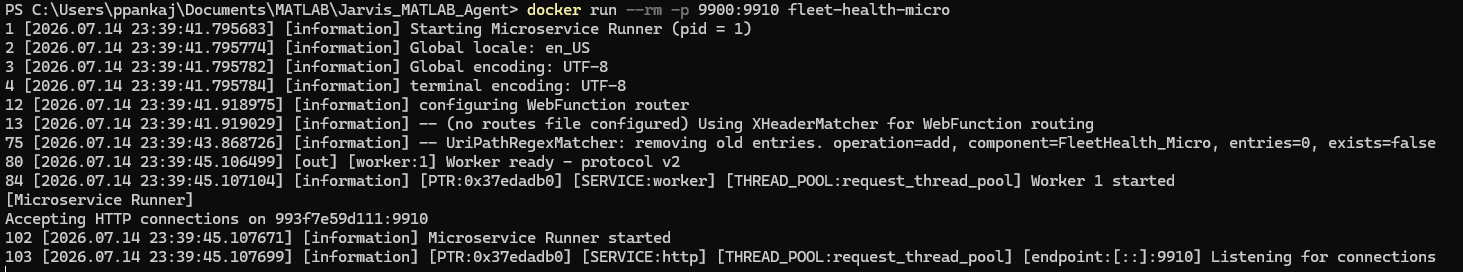

% !curl -H Content-Type:application/json -d "{\"nargout\":3,\"rhs\":[56.5, 19.0, 553.9, 276.76, 73.688, 99.81, 91.07]}" http://localhost:9900/PROD_predict/monitorHealthKPIs

#### Call microservice from anywhere (Example using MATLAB REST API call)

%% Test Microservice via HTTP
url = 'http://localhost:9900/FleetHealth_Micro/monitorEngineFleet';
options = weboptions('MediaType','application/json','Timeout',30);

% Build JSON payload: {"nargout":4,"rhs":[[[row1],...,[rowN]], {mwdata/mwsize/mwtype}]}
tickArray = numericData(1:9, :); % 9x362 double
tickIDs = engineIDs(1:9);

rows = strings(9,1);
for i = 1:9
    rows(i) = "[" + strjoin(string(tickArray(i,:)), ",") + "]";
end
matrixJson = "[" + strjoin(rows, ",") + "]";
idsJson = jsonencode(struct('mwdata', {cellstr(tickIDs)}, 'mwsize', [1 9], 'mwtype', 'string'));
jsonBody = char('{"nargout":4,"rhs":[' + string(matrixJson) + ',' + string(idsJson) + ']}');

response = webwrite(url, jsonBody, options);

%% Parse Microservice Response
% lhs(1): faultClass — string (cell of chars from JSON)
% lhs(2): confidenceScores — 9x8 double (flat column-major, reshape by mwsize)
% lhs(3): rulEstimates — cell (Inf serialized as "Inf" string in JSON)
% lhs(4): healthIndicators — double

fc = string(response.lhs(1).mwdata);
conf = reshape(response.lhs(2).mwdata, response.lhs(2).mwsize');
hi = response.lhs(4).mwdata;

% RUL: parse cell — JSON cannot represent Inf, server returns "Inf" as char
rulRaw = response.lhs(3).mwdata;
rul = zeros(numel(rulRaw), 1);
for i = 1:numel(rulRaw)
    if ischar(rulRaw{i}) && strcmp(rulRaw{i}, 'Inf')
        rul(i) = Inf;
    else
        rul(i) = double(rulRaw{i});
    end
end

fprintf("\n=== Microservice HTTP Response (9 engines) ===\n\n");
for i = 1:9
    if isinf(rul(i)), r = 'Inf'; else, r = sprintf('%d', rul(i)); end
    [~, maxIdx] = max(conf(i,:));
    fprintf("  %s | Pred: %-10s | Conf: %5.1f%% | HI: %+.3f | RUL: %4s (true: %d)\n", ...
        tickIDs(i), fc(i), conf(i,maxIdx)*100, hi(i), r, shuffledData.RUL(i));
end
fprintf("\n=== Deployment complete ===\n");

**Call MW Internal MPS Hosted Analytics Package**

%% Test MPS Deployment via "HTTP" (not HTTPS)
url = 'http://ipws-mps.mathworks.com/FleetHealth_Micro/monitorEngineFleet';
options = weboptions('MediaType','application/json','Timeout',30);

% Build JSON payload: {"nargout":4,"rhs":[[[row1],...,[rowN]], {mwdata/mwsize/mwtype}]}
tickArray = numericData(1:9, :); % 9x362 double
tickIDs = engineIDs(1:9);

rows = strings(9,1);
for i = 1:9
    rows(i) = "[" + strjoin(string(tickArray(i,:)), ",") + "]";
end
matrixJson = "[" + strjoin(rows, ",") + "]";
idsJson = jsonencode(struct('mwdata', {cellstr(tickIDs)}, 'mwsize', [1 9], 'mwtype', 'string'));
jsonBody = char('{"nargout":4,"rhs":[' + string(matrixJson) + ',' + string(idsJson) + ']}');

response = webwrite(url, jsonBody, options)

response = struct with fields:
    lhs: [4×1 struct]
